# A how to guide in using the Entropy Coefficient Estimator class. Generate multilevel temperature signals for each SoC and estimate the entropy coefficient

**WMG, University of Warwick, TVT, Karlsruhe Institute of Technology**

W.D. Widanage 05/10/2021 (Still quite)

## Step 1: Generate a multilevel temperature signal

Generate a second reference signal with different settings

clear
clc
close all

% Generate a reference signal with the default settings and plot the signal
ecObj = EntropyCoeffEstimator();
ecObj.PlotRefSig

% Generate a second reference signal with different settings and plot the
% signal
ecObj = EntropyCoeffEstimator("Tmin_degC",10,"Tmax_degC",50,"numLevels",5,"startTemp",30,"fMax_Hz",1.2E-3,"Ts_s",2,"Periods",4,"fileName","refSig_1050_60per.csv");
ecObj.PlotRefSig


## Step 2: Import measured OCV and temperature data

dataPth = what('Measurement_Data/measurements_Aug2023').path;
hdrNames = ["time", "TEC1", "TEC2", "BoxTop", "TabAnode", "SurfaceBottomAnode", "SurfaceTopAnode", "SurfaceBottomCathode", "SurfaceTopCathode", "TabCathode", "SurfaceTopCenter", "SurfaceBottomCenter", "CoolingBlockTop", "Ambient", "U"];
freqTextFilesInfo = dir(fullfile(dataPth,"*Frequency.txt"));
z = 80; % SoC break point
zz = find(z==(0:5:100));

kerObj = EntropyCoeffEstimator();
kerObj.ImportRefSig("filePth",fullfile(dataPth,"refSig","refSig_1050_July2022.mat"));             % Import reference signal
kerObj.ImportExpData("filePth",fullfile(dataPth,freqTextFilesInfo(zz).name),"HdrNames",hdrNames);



## Step 3: Estimate dudt

kerObj.EstimateEntropyCoeff(modelOrder_num=1,modelOrder_denom=4,transientOnOff="on");



Iteration terminated:  Maximum iteration reached, iterMax = 5000.

LM Regressor rank deficient at iteration 5000 
 Estimated parameters are NON-UNIQUE.
 Lls regressor is rank defficient. Rank = 5 instead of 6. 
Parameters estimated from a subspace. 


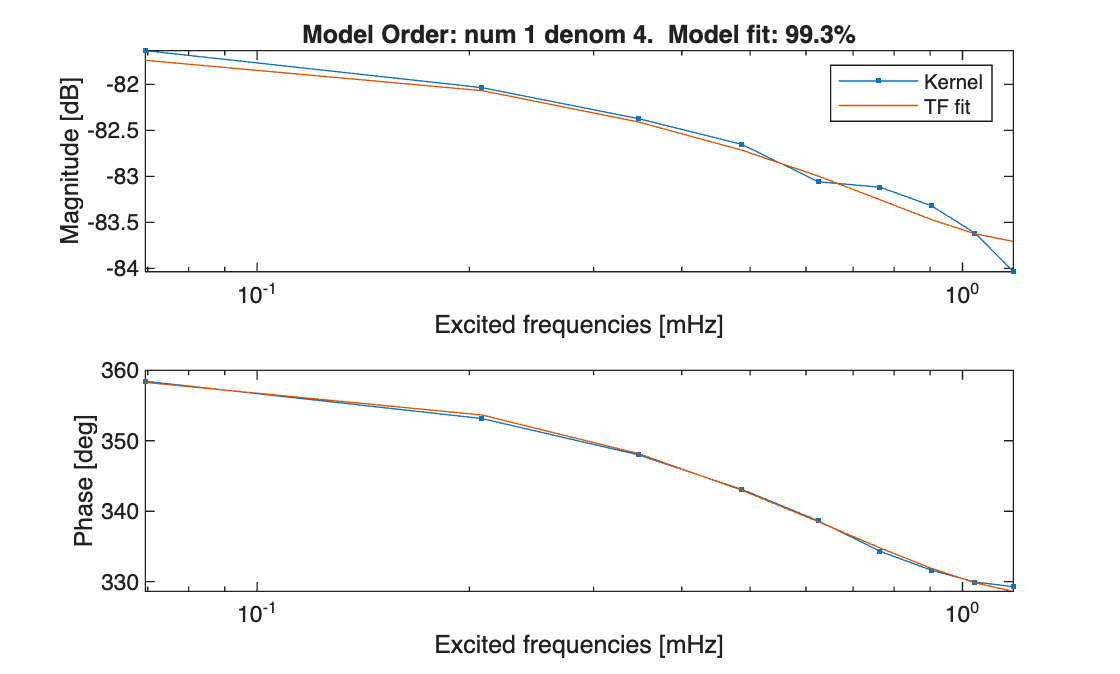

dUdTK = kerObj.results.dUdT_mVpK;
dUdTK_std = kerObj.results.dUdT_std;
kerObj.PlotKernelFit

kerObj.results.dUdT_mVpK

ans = 0.0825

kerObj.results.dUdT_std

ans = 0.0020